## Import

 
% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Time", "Time_s_", "IntensityCh1"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

[file, folder] = uigetfile('*.txt');
fullfile(folder, file)

ans = 'U:\Projekte an Analysis1\Christian\Misc\Hannah\230914\vCMC_Myh6-Piezo1-m_Tam+_stT_2mMCa_S01Z01L01-2.txt'

% Import the data
tbl = readtable(fullfile(folder, file), opts);

% Clear temporary variables
clear opts

% Display results
tbl

tbl = 65107×3 table
    Time     Time_s_     IntensityCh1
    ____    _________    ____________

      1             0       44.586   
      2     0.0009216       45.588   
      3     0.0018432       43.332   
      4     0.0027648       44.123   
      5     0.0036864       45.709   
      6      0.004608       46.361   
      7     0.0055296       45.961   
      8     0.0064512       46.098   
      9     0.0073728       46.109   
     10     0.0082944       47.268   
     11      0.009216       47.586   
     12      0.010138       45.107   
     13      0.011059       44.855   
     14      0.011981       45.287   
     15      0.012902       46.385   
     16      0.013824       46.625   


## Cleanup and Prep.

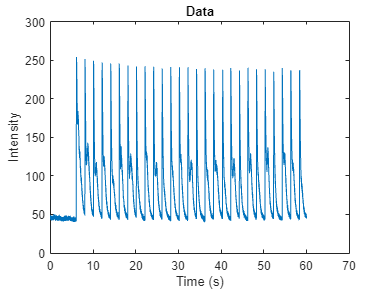

 
tbl=tbl(~any(ismissing(tbl),2),:);
tbl = tbl(:,2:3);
tbl.Properties.VariableNames = {'Time', 'Intensity'};
plot(tbl.Time, tbl.Intensity)
title("Data")
xlabel("Time (s)")
ylabel("Intensity")

## Smooth

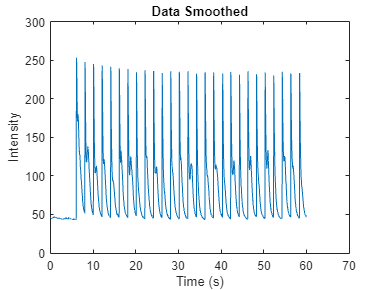

 
tbl = smoothdata(tbl,"movmedian",50,"DataVariables","Intensity");
plot(tbl.Time, tbl.Intensity)
title("Data Smoothed")
xlabel("Time (s)")
ylabel("Intensity")

Time = tbl.Time;
Intensity = tbl.Intensity;

## Find Peaks

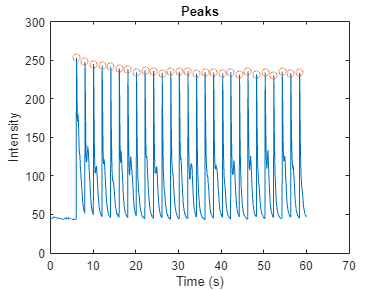

 
MinPeakProminence = 10;
MinPeakDistance = 1;
[pks,timePeak] = findpeaks(Intensity, Time ,'MinPeakProminence',MinPeakProminence,'MinPeakDistance', MinPeakDistance); %Prominence: https://de.mathworks.com/help/signal/ug/prominence.html
peakInterval = diff(timePeak);
plot(Time,Intensity, timePeak,pks,'o')
xlabel('Time (s)')
ylabel('Intensity')
title("Peaks")

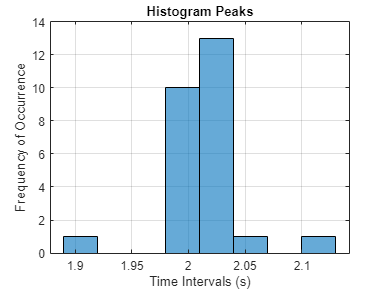

histogram(peakInterval)
title("Histogram Peaks")
grid on
xlabel('Time Intervals (s)')
ylabel('Frequency of Occurrence')

AverageDistance_Peaks = mean(diff(timePeak))

AverageDistance_Peaks = 2.0112

baselineDistance = -1.3;
for i = 1: numel(timePeak)
    [~, ix5] = min(abs(Time - (timePeak(i)-0.3)));
    [~, ix6] = min(abs(Time - (timePeak(i)+baselineDistance)));
    baseline(i) = median(Intensity(ix6:ix5));
end

## Fit

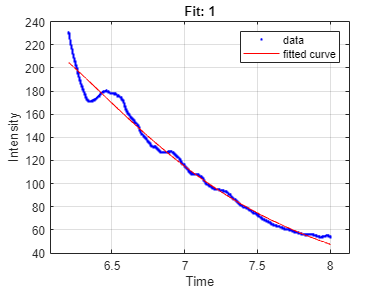

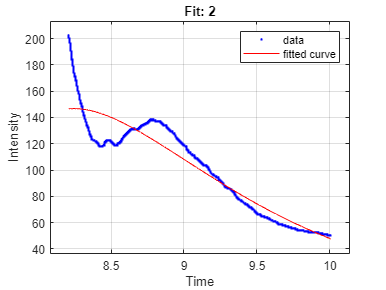

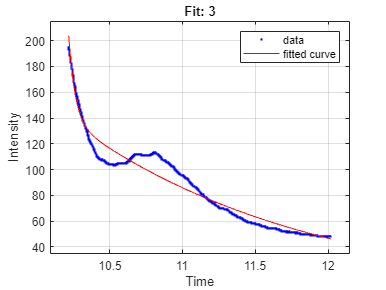

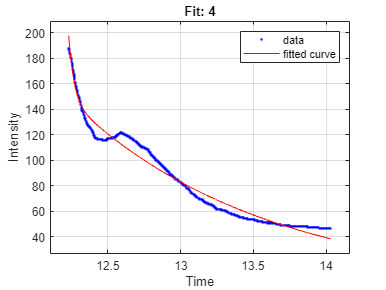

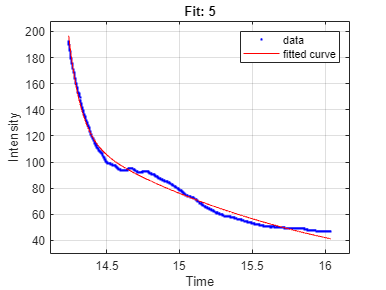

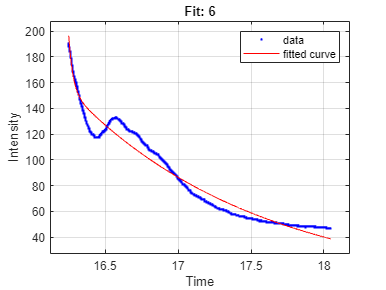

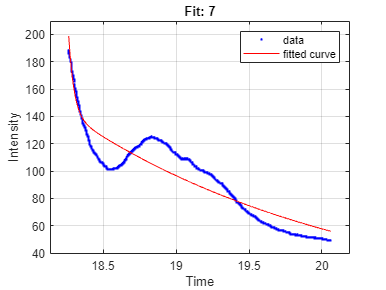

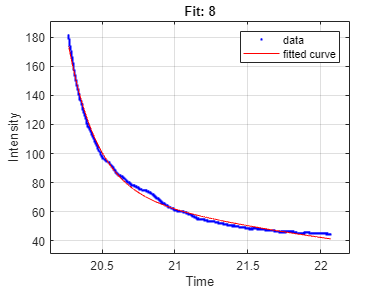

 
fitDistance = 1.9;
for i = 1: numel(timePeak)
    [~, ix1] = min(abs(Time - (timePeak(i)+0.1)));
    [~, ix2] = min(abs(Time - (timePeak(i)+fitDistance)));
    TimeFit = Time(ix1:ix2);
    IntensityFit = Intensity(ix1:ix2);
    [fitresult, gof] = createFit(TimeFit, IntensityFit);
    title(append("Fit: ", num2str(i)));
    axis padded
    tauFast = log(1/2) / fitresult.b;
    tauSlow = log(1/2) / fitresult.d;
    gof.tauSlow = tauSlow;
    gof.tauFast = tauFast;
    fitData(i) = struct('fit', fitresult, 'fitInfo', gof, 'Intensity', IntensityFit, 'Time', TimeFit);
end

## Taus

 
"T1/2 Slow"

ans = "T1/2 Slow"

for i = 1: numel(timePeak)
    slowTaus(i) = fitData(i).fitInfo.tauSlow;
    append(num2str(i),": ", num2str(slowTaus(i)))

end

ans = "1: 1.4305"

ans = "2: 1.0089"

ans = "3: 2.1919"

ans = "4: 1.7838"

ans = "5: 2.2607"

ans = "6: 1.7326"

ans = "7: 2.5918"

ans = "8: 3.8895"

ans = "9: -0.53096"

ans = "10: 2.167"

ans = "11: 3.6497"

ans = "12: 1.8689"

ans = "13: -0.87356"

ans = "14: 2.6846"

ans = "15: 6.3849"

ans = "16: 1.911"

ans = "17: 2.2874"

ans = "18: 4.7651"

ans = "19: 2.3738"

ans = "20: 7.0171"

ans = "21: 1.9788"

ans = "22: 3.5367"

ans = "23: 1.0157"

ans = "24: 10.2473"

ans = "25: 1.5811"

ans = "26: 1.7949"

ans = "27: 2.5585"

"T1/2 Fast"

ans = "T1/2 Fast"


for i = 1: numel(timePeak)
    fastTaus(i) = fitData(i).fitInfo.tauFast;
    append(num2str(i),": ", num2str(fastTaus(i)))
end

ans = "1: 0.54732"

ans = "2: 1.0088"

ans = "3: 0.058947"

ans = "4: 0.048796"

ans = "5: 0.11255"

ans = "6: 0.038744"

ans = "7: 0.048278"

ans = "8: 0.2592"

ans = "9: 1.3451"

ans = "10: 0.055238"

ans = "11: 0.25212"

ans = "12: 0.097325"

ans = "13: 1.1348"

ans = "14: 0.059444"

ans = "15: 0.29893"

ans = "16: 0.08733"

ans = "17: 0.048405"

ans = "18: 0.35967"

ans = "19: 0.055414"

ans = "20: 0.30625"

ans = "21: 0.049273"

ans = "22: 0.36551"

ans = "23: 1.0158"

ans = "24: 0.32074"

ans = "25: 0.55631"

ans = "26: 0.057592"

ans = "27: 0.19165"

append("Median Tau1/2 Slow: ", num2str(median(slowTaus)), " +- ", num2str(std(slowTaus)))

ans = "Median Tau1/2 Slow: 2.1919 +- 2.2676"

append("Median Tau1/2 Fast: ", num2str(median(fastTaus)), " +- ", num2str(std(fastTaus)))

ans = "Median Tau1/2 Fast: 0.19165 +- 0.37593"

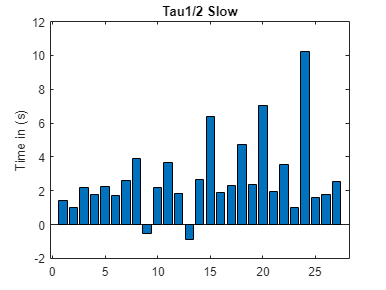


figure;bar(slowTaus)
title("Tau1/2 Slow")
ylabel("Time in (s)")

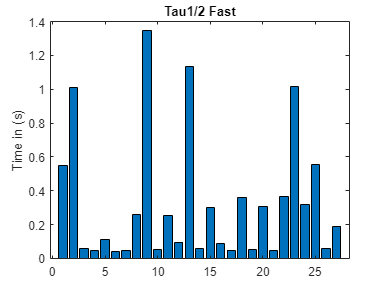

figure;bar(fastTaus)
title("Tau1/2 Fast")
ylabel("Time in (s)")

## Time To

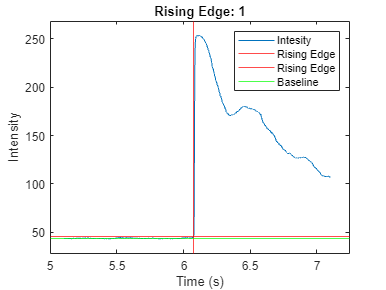

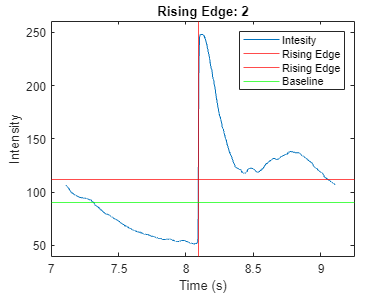

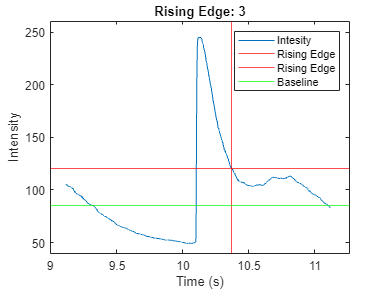

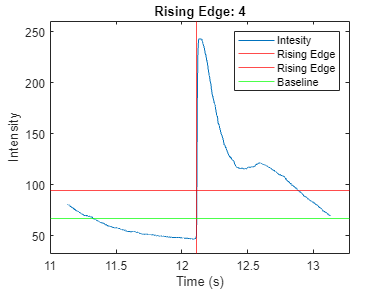

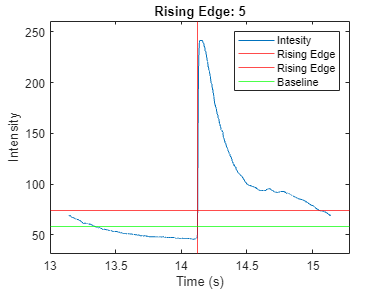

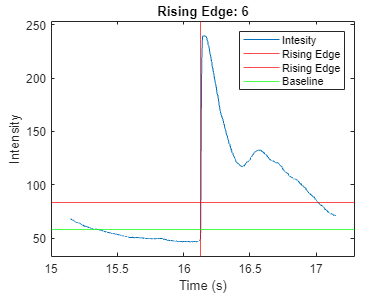

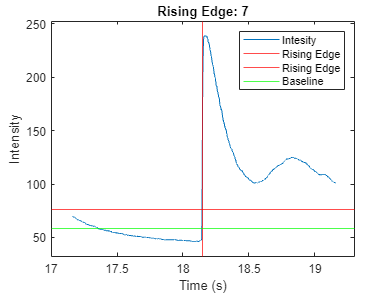

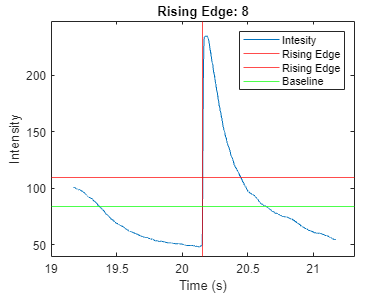

 
timeToVecStr ="25;50;75;90;100"; %Seperate Values by semicolon ;
splitStr = strsplit(timeToVecStr, ';');
timeToVec = arrayfun(@str2num,splitStr);
timeToTable = table('Size',[0,5],'VariableTypes', repelem("double",numel(splitStr)), 'Variablenames',append("Time to: ",splitStr, " (ms)"));
for i = 1: numel(timePeak)
    [~, ix3] = min(abs(Time - (timePeak(i)-1)));
    [~, ix4] = min(abs(Time - (timePeak(i)+1)));
    TimeTimeToCalc = Time(ix3:ix4);
    IntensityTimeToCalc = Intensity(ix3:ix4);
    try
        ipt = findchangepts(IntensityTimeToCalc,'Statistic',"std");
        figure;
        plot(TimeTimeToCalc, IntensityTimeToCalc);
        title(append("Rising Edge: ", num2str(i)));
        xlabel("Time (s)")
        ylabel("Intensity")
        axis padded
        xline(TimeTimeToCalc(ipt), 'Color', 'red');
        yline(IntensityTimeToCalc(ipt), 'Color', 'red');
        yline(baseline(i), 'Color' , 'green');
        legend({'Intesity','Rising Edge','Rising Edge', 'Baseline'});
        IntensityTimeToCalc = 100 * normalize(IntensityTimeToCalc,  "range");
        IntensityTimeToCalc = IntensityTimeToCalc(ipt:find(timePeak(i) == TimeTimeToCalc));
        TimeTimeToCalc = TimeTimeToCalc(ipt:find(timePeak(i) == TimeTimeToCalc));
        [~,closestIndex] =  min(abs(IntensityTimeToCalc-timeToVec));
        timeToTable(i,:) = array2table((TimeTimeToCalc(closestIndex)-TimeTimeToCalc(1))');
    catch
        timeToTable(i,:) = table(NaN);
    end

end


timeToTable

timeToTable = 27×5 table
    Time to: 25 (ms)    Time to: 50 (ms)    Time to: 75 (ms)    Time to: 90 (ms)    Time to: 100 (ms)
    ________________    ________________    ________________    ________________    _________________

       0.0064512           0.0082944            0.010138            0.011981            0.029491     
               0           0.0009216           0.0027648           0.0055296            0.016589     
             NaN                 NaN                 NaN                 NaN                 NaN     
               0           0.0018432            0.004608           0.0073728             0.01751     
       0.0009216           0.0027648           0.0055296           0.0082944            0.015667     
       0.0009216           0.0027648            0.004608           0.0082944             0

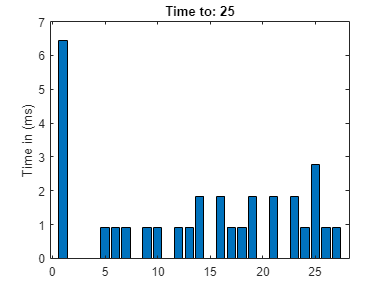

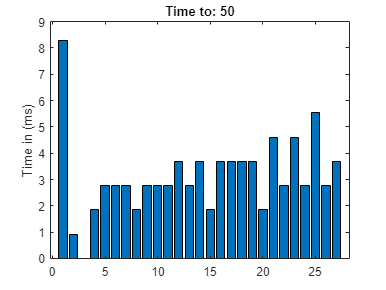

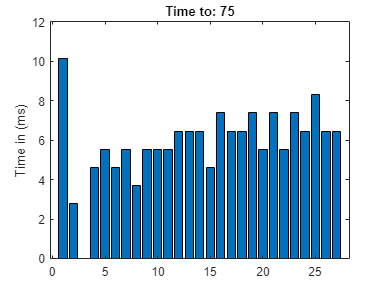

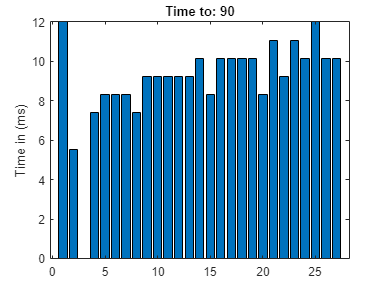

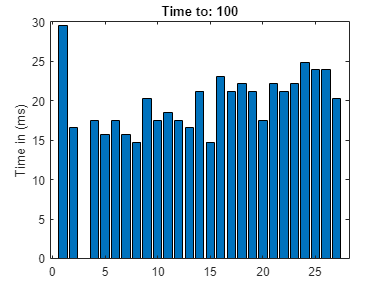


for i = 1:numel(timeToVec)
    figure;bar(timeToTable{:,i}*1000)
    title(append("Time to: ", splitStr(i)))
    ylabel("Time in (ms)")
end

## Data

 
dataTable = table(fastTaus', slowTaus', pks, baseline', pks - baseline', pks ./ baseline', timePeak);
dataTable.Properties.VariableNames ={'FastTau1/2 (s)', 'SlowTau1/2 (s)', 'Peak Intensity', 'Baseline Intensity', 'Peak Intensity Abs','F/F0' ,'Peak Time (s)'};
dataTable = [dataTable timeToTable];
dataTable

dataTable = 27×12 table
    FastTau1/2 (s)    SlowTau1/2 (s)    Peak Intensity    Baseline Intensity    Peak Intensity Cor     F/F0     Peak Time (s)    Time to: 25 (ms)    Time to: 50 (ms)    Time to: 75 (ms)    Time to: 90 (ms)    Time to: 100 (ms)
    ______________    ______________    ______________    __________________    __________________    ______    _____________    ________________    ________________    ________________    ________________    _________________

        0.54732            1.4305           253.11              43.856                209.25          5.7713     

## Save .Mat

 
uisave

## Save .csv

 
[folder, file] = uiputfile('*.csv')
writetable(dataTable, fullfile(file,folder))


## Save .html


 
[folder, file] = uiputfile('*.html')
export("AnalyseSparks.mlx",fullfile(file,folder),Format="html", OpenExportedFile=true, HideCode=true)